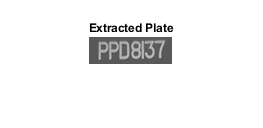

I = rgb2gray(imresize(imread("Plate10.jpg") , [512,512]));

Icrop = imcrop(I , [128 128 256 384]);
corners = detectHarrisFeatures(Icrop);

strongestCorner = corners.selectStrongest(30); 
TF = rmoutliers(strongestCorner.Location,'median');
 
X = min(TF(:,1));
Y = min(TF(:,2));
h = max(TF(:,2)) - Y ;
w = max(TF(:,1)) - X ;

new= imcrop(Icrop , [X-10  Y-5  w+20 h+10]);
figure,imshow(new);title("Extracted Plate");

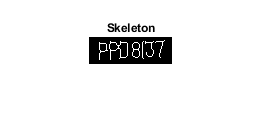


Iafter = imcomplement(imbinarize(uint8(new)));
skel = bwmorph(imcomplement(Iafter),'skel',Inf);
figure,imshow(skel);title("Skeleton"); 

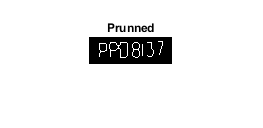

prunned = bwmorph(skel , "spur" , 3);
figure,imshow(prunned);title("Prunned");


%se = strel('rectangle' , [2,1]);
%figure,imshow(imopen(prunned , se));title("OPEN"); 

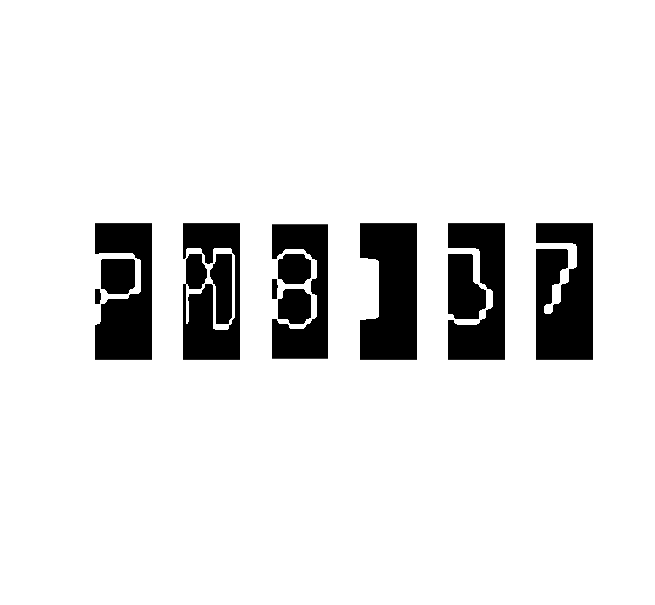


se2 = strel('rectangle' , [160,2]);
sh = prunned;
for k=1:1
   sh =  imdilate(sh,se2);
end



[m,n] = size(sh); 
sh(1:m,1:3) = 0 ; 
head = 0 ;
tail = 0 ;
character_head = [];
character_width = [] ; 
j = 1 ; 
while j < n
    if head == 0 
            if sh(m,j) ~= sh(m,max([1,j-1]))
                head = j ;
            else
                j = j + 1; 
            end
    else
        if head ~= 0 && tail == 0 
            if sh(m,j) == 1 
                j = j + 1;
            else 
                tail = j ;
                character_head = [character_head , head]; 
                character_width = [character_width , tail-head];
                j = j + 1 ; 
                head = 0 ; 
                tail = 0 ;
            end
        else
            j = j + 1; 
            head = 0 ; 
            tail = 0 ; 
        end 
    end 
end

image = [] ; 
for i = 1:length(character_head)
    [h z] = size(prunned);  
    X = character_head(i);
    Y = 0;
    w = character_width(i);
    im = imcrop(prunned , [X Y w h]);
    im = imresize(im, [1200 500]);
    image = [image im]; 
    [p q] = size(im);
    subplot(1,length(character_head) ,i ), imshow(mat2gray(im));
end